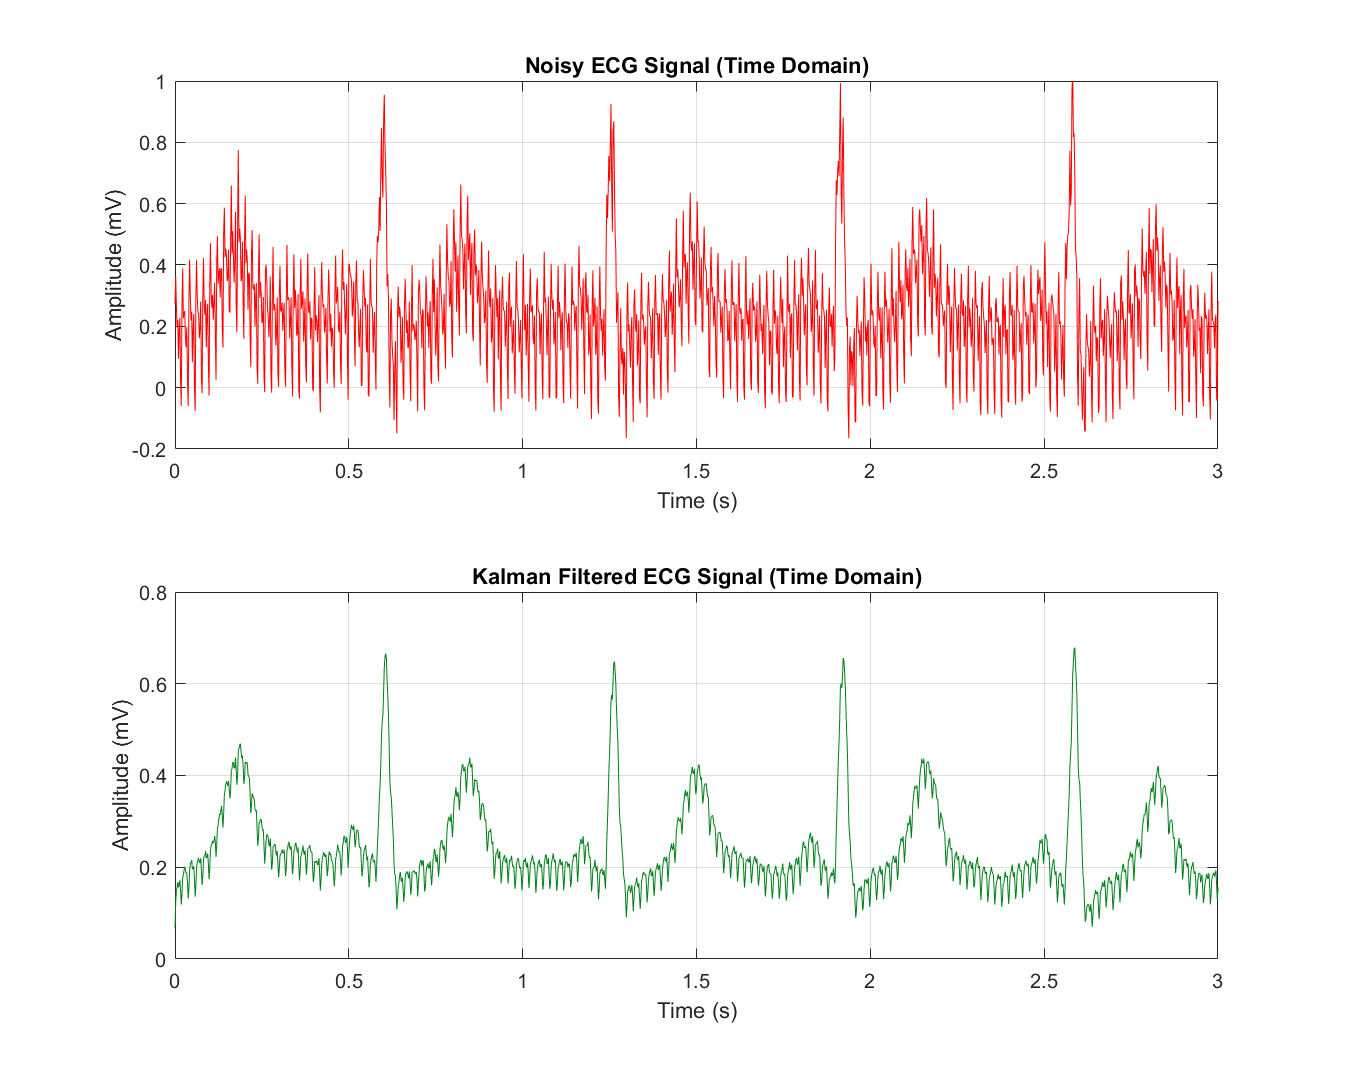

%% 2. Kalman Filter for ECG Denoising

clear; clc; close all;

%%  Load ECG data
load("ECG_rec (2).mat");       % Noisy ECG
load("idealECG (1).mat");      % Clean ECG

% Assign variables
ecg_noisy = nECG(:);
ecg_clean = idealECG(:);

% Sampling frequencies
fs_noisy = 500;
fs_clean = 128;

% Resample clean ECG from 128 Hz → 500 Hz
idealECG_up = resample(ecg_clean, fs_noisy, fs_clean);

% Equalize lengths
minLen = min(length(ecg_noisy), length(idealECG_up));
ecg_noisy = ecg_noisy(1:minLen);
idealECG_up = idealECG_up(1:minLen);
fs = fs_noisy;
t = (0:minLen-1)/fs;

%% Load Wiener filter weights from Task 1
% Make sure Task 1 saved: save('wiener_weights.mat','w_opt');
load('wiener_weights.mat','w_opt');

% (i) Kalman filter design
x_est = mean(w_opt);     % initial state (Wiener mean)
P_est = 1;               % initial estimate covariance
Q = 0.1;                 % process noise covariance
R = 4;                   % measurement noise covariance

filtered_ECG = zeros(minLen,1);
input_ECG = ecg_noisy - mean(ecg_noisy);  % DC offset correction

%% Apply Kalman filter
for k = 1:minLen
    % Prediction
    x_pred = x_est;
    P_pred = P_est + Q;

    % Update
    K = P_pred / (P_pred + R);
    x_est = x_pred + K * (input_ECG(k) - x_pred);
    P_est = (1 - K) * P_pred;

    % Store filtered output
    filtered_ECG(k) = x_est;
end

%% (ii) Time-domain comparison (first few seconds for visualization)
figure('Position',[100,100,1000,800]);

subplot(2,1,1);
plot(t, input_ECG, 'r');
title('Noisy ECG Signal (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
xlim([0 3]); ylim([-0.2 1]); grid on;

subplot(2,1,2);
plot(t, filtered_ECG, 'Color', [0 0.5 0.1]);
title('Kalman Filtered ECG Signal (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
xlim([0 3]); ylim([-0 0.8]); grid on;

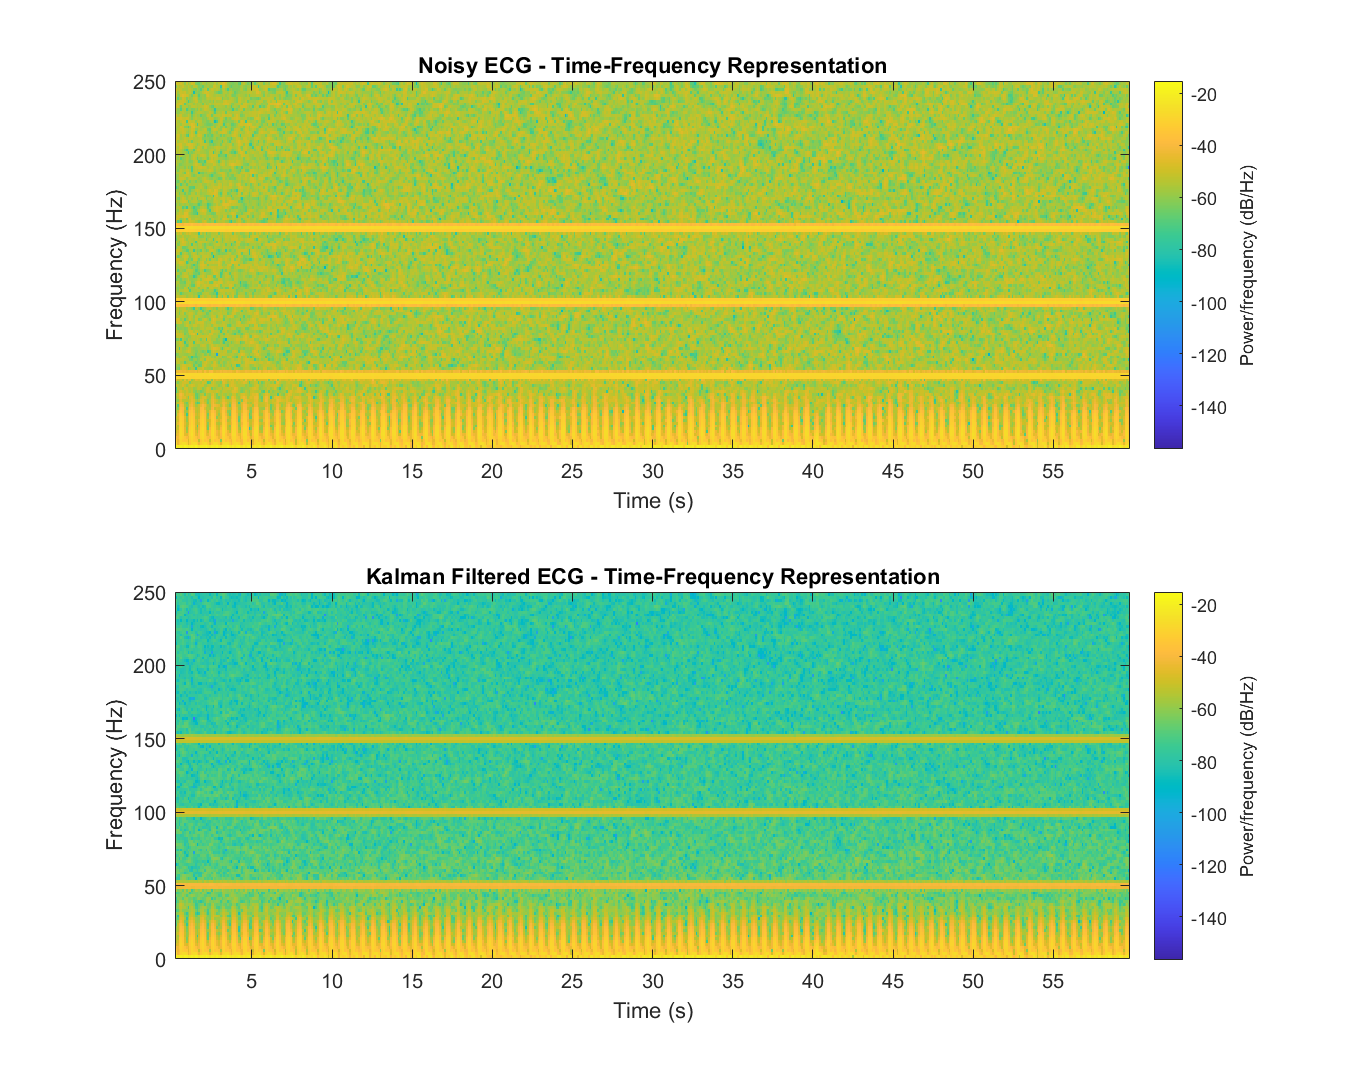


%% (ii) Time–frequency comparison
figure('Position',[100,100,1000,800]);

subplot(2,1,1);
spectrogram(input_ECG, 256, 200, 256, fs, 'yaxis');
title('Noisy ECG - Time-Frequency Representation');
ylim([0 250]);

subplot(2,1,2);
spectrogram(filtered_ECG, 256, 200, 256, fs, 'yaxis');
title('Kalman Filtered ECG - Time-Frequency Representation');
ylim([0 250]); 